# Training data 

More on [https://github.com/slevin48/ai-workflow](https://github.com/slevin48/ai-workflow) 

## Data access

training_dataset = "2021-03-06-1";

### Get controller data

data = readtable("D:\devel\AI-workflow\samples\"+training_dataset+"\data.csv");
data = renamevars(data,["Var1","Var2","Var3","Var4","Var5","Var6"],["img", "x", "y", "r2", "l2", "r1"]);
erase(string(data(1,:).img),"samples/"+training_dataset+"/")

ans = "img_0.png"

data.frame = erase(string(data.img),"samples/"+training_dataset+"/")

data = 1672×7 table
                    img                        x             y           r2       l2    r1       frame    
    ___________________________________    __________    __________    _______    __    __    ____________

    {'samples/2021-03-06-1/img_0.png' }     -0.015747     -0.023621          0    0     0     "img_0.png" 
    {'samples/2021-03-06-1/img_1.png' }     -0.015747     -0.023621          0    0     0     "img_1.png" 
    {'samples/2021-03-06-1/img_2.png' }     -0.015747     -0.015747          0    0     0     "img_2.png" 
    {'samples/2021-03-06-1/img_3.png' }     -0.015747     -0.023621    0.72656    0     0     "img_3.png" 
    {'samples/2021-03-06-1/img_4.png' }     -0.015747     -0.023621    0.99609    0     0     "img_

data(data.frame == "img_0.png",{'x','y','r2','l2','r1'})

ans = 1×5 table
        x            y        r2    l2    r1
    _________    _________    __    __    __

    -0.015747    -0.023621    0     0     0 


data(1,:)

ans = 1×7 table
                   img                        x            y        r2    l2    r1       frame   
    __________________________________    _________    _________    __    __    __    ___________

    {'samples/2021-03-06-1/img_0.png'}    -0.015747    -0.023621    0     0     0     "img_0.png"


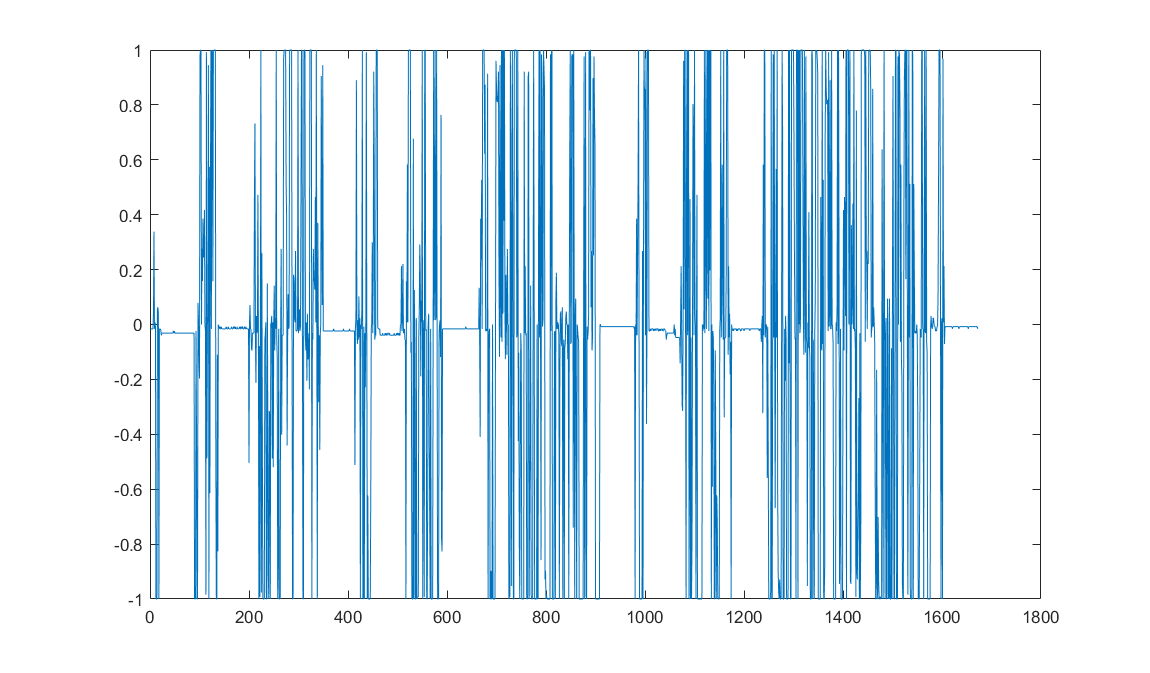

plot(data.x)

### Get images

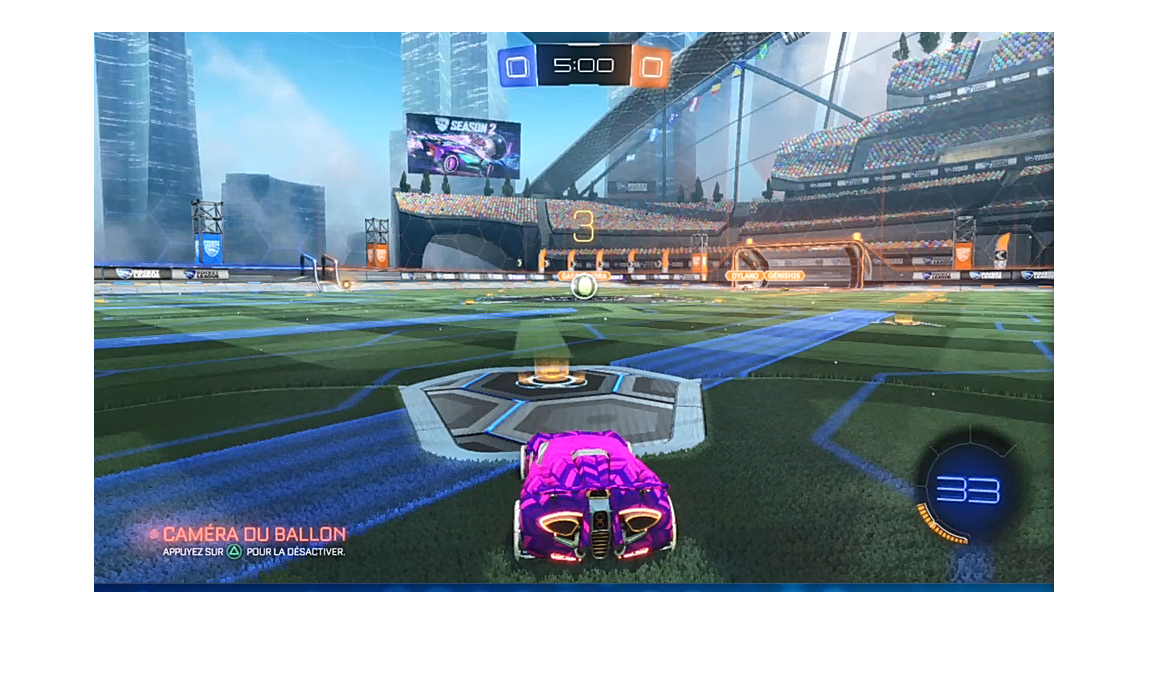

% training_dataset = "2021-03-06-1";
training_data_0 = imread("D:\devel\AI-workflow\samples\"+training_dataset+"\img_0.png");
imshow(training_data_0)

len = length(ls("D:\devel\AI-workflow\samples\"+training_dataset))

len = 1675

i = 783;
training_img = imread("D:\devel\AI-workflow\samples\"+training_dataset+"\img_"+string(i)+".png");
data(i,:)

ans = 1×7 table
                    img                        x           y          r2       l2    r1        frame    
    ____________________________________    ________    ________    _______    __    __    _____________

    {'samples/2021-03-06-1/img_782.png'}    -0.99997    -0.28345    0.99609    0     0     "img_782.png"


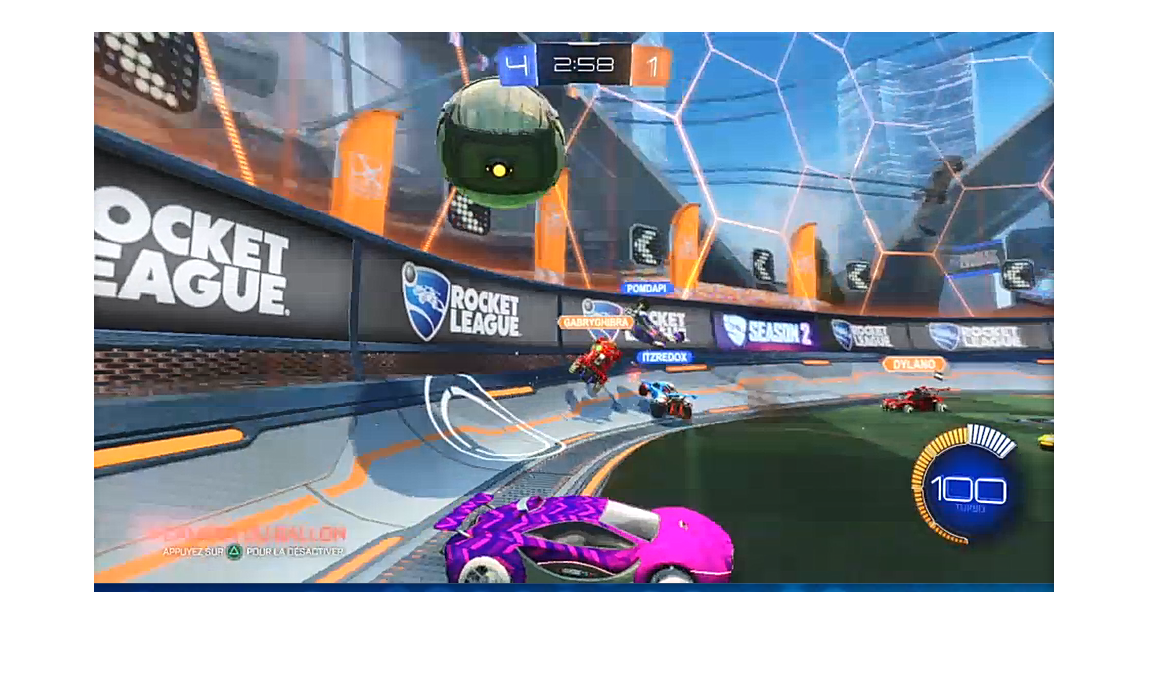

imshow(training_img)

### Browse training data with an app